# ENGR3390: Fun-Robo ACT Lab: Servos

Elvis Wolcott and Jackie Zeng

Created 2/17/2021 - Revision 1

**Demonstration of using RCServoArduino()**

Aims a laser pointer using two servo motors attached to an Arduino-like microcontroller using PWM.

Works with the Spark Fun Wireless Motor Driver (DEV-14285), but should work with any Arduino setup wired the same.

The pan motor should be connected to PWM 9 and tilt to PWM 11.

The laser pointer should be connected to Digital 12.

The program prompts for positions 0-1 and then sets the position of the servo. Different servos have different ranges of motions, so we will measure the actual range and enter it to the program to produce a calibration graph.

## Document Code

clc
clear

## Stuff you run once

% COM port (CHECK THIS ON YOUR SYSTEM!)
port = 'COM12';         % Elvis
%port = 'COM4';          % Jackie
disp('note: It takes about 10 seconds to download new code to the Arduino');

note: It takes about 10 seconds to download new code to the Arduino


[robotArduino, panServo, tiltServo, blinkLED] = SETUPARDUINO(port);
% blink the on board LED
Blink(robotArduino, blinkLED, 3);
disp("Warning: Pan and Tilt Servos Active!");

% collected data
nTests = input(['Enter number of servo test positions, ' ...
    'followed by enter: ']);

% create a variable to hold experimental position data
panServoData = zeros(nTests,2);
tiltServoData = zeros(nTests, 2);

r = rateControl(0.25);                % create a 0.25 hz loop rate
reset(r);                             % reset loop time to zero

## Stuff you run multiple times

% test loop that collects samples
controlFlag = 1;                % loop progress
while (controlFlag < nTests+1)  % loop until flag is unset
    commandAngle = SENSE();     % desired angle from operator (used for both)
    panAngle = commandAngle;
    tiltAngle = commandAngle;
    THINK();                    % no op
    
    % set servo positions
    ACTRCServoArduino(panServo, tiltServo, panAngle, tiltAngle);
    
    % store requested and actual positions
    panServoData(controlFlag, 1) = input("Enter actual pan angle (degrees):");
    panServoData(controlFlag, 2) = panAngle;
    tiltServoData(controlFlag, 1) = input("Enter actual tilt angle (degrees):");
    tiltServoData(controlFlag, 2) = tiltAngle;
    
    % blink to indicate completion
    Blink(robotArduino, blinkLED, 1);
    
    % loop iteration
    waitfor(r);
    controlFlag = controlFlag + 1;
end

## Mission Data Processing

plot(panServoData(:, 1), panServoData(:, 2), '-*');
hold on;
plot(tiltServoData(:, 1), tiltServoData(:, 2), '-*');
hold off;
xlabel('Actual Angle');
ylabel('Commanded Angle');
legend('Pan Servo', 'Tilt Servo');

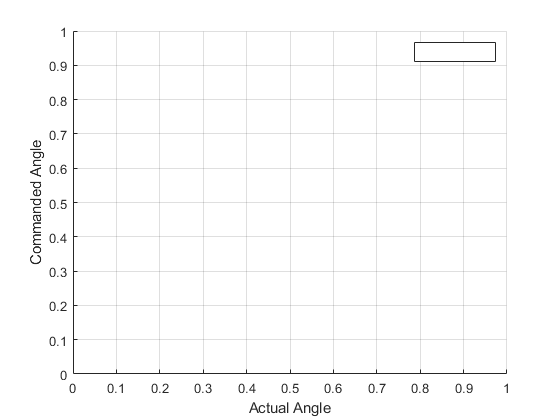

grid;

% save calibration panServoData tiltServoData

## Test Angles

Run this section with different values to test different angles

panAngle = SENSE_panAngle();
tiltAngle = SENSE_tiltAngle();

% set servo positions
ACTRCServoArduino(panServo, tiltServo, panAngle, tiltAngle);
laserOn(robotArduino);

laserOff(robotArduino);

## Test XY Position

Run this section with different XYs to move laser to diff parts of the wall. Make sure to turn off the laser after testing. 

(0,0) is straight in front of the robot. 

[panAngle, tiltAngle] = SENSE_XY(25);
% set servo positions
ACTRCServoArduino(panServo, tiltServo, panAngle, tiltAngle);

laserOn(robotArduino)

laserOff(robotArduino);

## Test Draw Square

The last input argument is how many times you want to draw the square

DrawSquare(robotArduino, panServo, tiltServo, 10);

## Load Complex Drawing

The points are generated using the HTML file in this directory (because MATLAB doens't have a easy way to process SVG files).

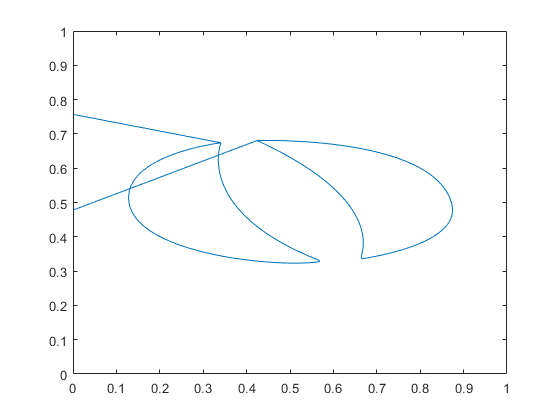

i = 1

ans =    -0.1519    0.3611


panAngle = 0.6849

tiltAngle = 0.5131

i = 2

ans =    -0.1266    0.3617


panAngle = 0.6924

tiltAngle = 0.5128

i = 3

ans =    -0.1013    0.3618


panAngle = 0.6999

tiltAngle = 0.5126

i = 4

ans =    -0.0760    0.3615


panAngle = 0.7074

tiltAngle = 0.5126

i = 5

ans =    -0.0507    0.3610


panAngle = 0.7149

tiltAngle = 0.5127

i = 6

ans =    -0.0254    0.3601


panAngle = 0.7224

tiltAngle = 0.5130

i = 7

ans =    -0.0002    0.3590


panAngle = 0.7300

tiltAngle = 0.5134

i = 8

ans =     0.0251    0.3576


panAngle = 0.7375

tiltAngle = 0.5139

i = 9

ans =     0.0503    0.3558


panAngle = 0.7450

tiltAngle = 0.5146

i = 10

ans =     0.0755    0.3538


panAngle = 0.7525

tiltAngle = 0.5154

i = 11

ans =     0.1007    0.3515


panAngle = 0.7600

tiltAngle = 0.5164

i = 12

ans =     0.1259    0.3488


panAngle = 0.7674

tiltAngle = 0.5175

i = 13

ans =     0.1510    0.3459


panAngle = 0.7748

tiltAngle = 0.5187

i = 14

ans =     0.1761    0.3425


panAngle = 0.7822

tiltAngle = 0.5201

i = 15

ans =     0.2011    0.3389


panAngle = 0.7896

tiltAngle = 0.5217

i = 16

ans =     0.2261    0.3349


panAngle = 0.7969

tiltAngle = 0.5234

i = 17

ans =     0.2510    0.3305


panAngle = 0.8042

tiltAngle = 0.5253

i = 18

ans =     0.2758    0.3256


panAngle = 0.8114

tiltAngle = 0.5273

i = 19

ans =     0.3005    0.3204


panAngle = 0.8186

tiltAngle = 0.5295

i = 20

ans =     0.3252    0.3147


panAngle = 0.8257

tiltAngle = 0.5319

i = 21

ans =     0.3497    0.3085


panAngle = 0.8327

tiltAngle = 0.5344

i = 22

ans =     0.3741    0.3019


panAngle = 0.8397

tiltAngle = 0.5372

i = 23

ans =     0.3983    0.2947


panAngle = 0.8466

tiltAngle = 0.5402

i = 24

ans =     0.4224    0.2869


panAngle = 0.8534

tiltAngle = 0.5434

i = 25

ans =     0.4463    0.2785


panAngle = 0.8600

tiltAngle = 0.5468

i = 26

ans =     0.4699    0.2694


panAngle = 0.8666

tiltAngle = 0.5504

i = 27

ans =     0.4932    0.2596


panAngle = 0.8730

tiltAngle = 0.5543

i = 28

ans =     0.5162    0.2491


panAngle = 0.8794

tiltAngle = 0.5585

i = 29

ans =     0.5388    0.2377


panAngle = 0.8855

tiltAngle = 0.5629

i = 30

ans =     0.5609    0.2255


panAngle = 0.8915

tiltAngle = 0.5676

i = 31

ans =     0.5825    0.2123


panAngle = 0.8973

tiltAngle = 0.5727

i = 32

ans =     0.6034    0.1981


panAngle = 0.9029

tiltAngle = 0.5781

i = 33

ans =     0.6236    0.1828


panAngle = 0.9082

tiltAngle = 0.5838

i = 34

ans =     0.6428    0.1665


panAngle = 0.9133

tiltAngle = 0.5899

i = 35

ans =     0.6610    0.1489


panAngle = 0.9180

tiltAngle = 0.5964

i = 36

ans =     0.6780    0.1302


panAngle = 0.9224

tiltAngle = 0.6033

i = 37

ans =     0.6936    0.1102


panAngle = 0.9264

tiltAngle = 0.6106

i = 38

ans =     0.7075    0.0891


panAngle = 0.9300

tiltAngle = 0.6182

i = 39

ans =     0.7197    0.0670


panAngle = 0.9331

tiltAngle = 0.6261

i = 40

ans =     0.7300    0.0439


panAngle = 0.9357

tiltAngle = 0.6344

i = 41

ans =     0.7383    0.0200


panAngle = 0.9378

tiltAngle = 0.6429

i = 42

ans =     0.7446   -0.0045


panAngle = 0.9394

tiltAngle = 0.6516

i = 43

ans =     0.7486   -0.0294


panAngle = 0.9404

tiltAngle = 0.6604

i = 44

ans =     0.7490   -0.0547


panAngle = 0.9405

tiltAngle = 0.6694

i = 45

ans =     0.7454   -0.0797


panAngle = 0.9396

tiltAngle = 0.6782

i = 46

ans =     0.7378   -0.1038


panAngle = 0.9377

tiltAngle = 0.6868

i = 47

ans =     0.7267   -0.1265


panAngle = 0.9349

tiltAngle = 0.6950

i = 48

ans =     0.7126   -0.1475


panAngle = 0.9313

tiltAngle = 0.7025

i = 49

ans =     0.6962   -0.1667


panAngle = 0.9271

tiltAngle = 0.7096

i = 50

ans =     0.6780   -0.1843


panAngle = 0.9224

tiltAngle = 0.7160

i = 51

ans = 1×2
    0.6584   -0.2003


panAngle = 0.9173

tiltAngle = 0.7220

i = 52

ans = 1×2
    0.6378   -0.2149


panAngle = 0.9119

tiltAngle = 0.7275

i = 53

ans = 1×2
    0.6164   -0.2283


panAngle = 0.9063

tiltAngle = 0.7326

i = 54

ans = 1×2
    0.5943   -0.2407


panAngle = 0.9004

tiltAngle = 0.7374

i = 55

ans = 1×2
    0.5717   -0.2520


panAngle = 0.8944

tiltAngle = 0.7418

i = 56

ans = 1×2
    0.5487   -0.2625


panAngle = 0.8882

tiltAngle = 0.7459

i = 57

ans = 1×2
    0.5254   -0.2723


panAngle = 0.8819

tiltAngle = 0.7498

i = 58

ans = 1×2
    0.5017   -0.2813


panAngle = 0.8754

tiltAngle = 0.7534

i = 59

ans = 1×2
    0.4779   -0.2897


panAngle = 0.8688

tiltAngle = 0.7569

i = 60

ans = 1×2
    0.4538   -0.2975


panAngle = 0.8621

tiltAngle = 0.7600

i = 61

ans = 1×2
    0.4296   -0.3047


panAngle = 0.8554

tiltAngle = 0.7630

i = 62

ans = 1×2
    0.4052   -0.3113


panAngle = 0.8485

tiltAngle = 0.7658

i = 63

ans = 1×2
    0.3806   -0.3175


panAngle = 0.8415

tiltAngle = 0.7684

i = 64

ans = 1×2
    0.3560   -0.3231


panAngle = 0.8345

tiltAngle = 0.7708

i = 65

ans = 1×2
    0.3312   -0.3280


panAngle = 0.8274

tiltAngle = 0.7729

i = 66

ans = 1×2
    0.3276   -0.3143


panAngle = 0.8264

tiltAngle = 0.7680

i = 67

ans = 1×2
    0.3333   -0.2897


panAngle = 0.8280

tiltAngle = 0.7588

i = 68

ans = 1×2
    0.3367   -0.2647


panAngle = 0.8290

tiltAngle = 0.7495

i = 69

ans = 1×2
    0.3380   -0.2394


panAngle = 0.8294

tiltAngle = 0.7401

i = 70

ans = 1×2
    0.3374   -0.2141


panAngle = 0.8292

tiltAngle = 0.7307

i = 71

ans = 1×2
    0.3349   -0.1890


panAngle = 0.8285

tiltAngle = 0.7213

i = 72

ans = 1×2
    0.3307   -0.1640


panAngle = 0.8273

tiltAngle = 0.7120

i = 73

ans = 1×2
    0.3250   -0.1394


panAngle = 0.8256

tiltAngle = 0.7028

i = 74

ans = 1×2
    0.3178   -0.1152


panAngle = 0.8236

tiltAngle = 0.6937

i = 75

ans = 1×2
    0.3092   -0.0914


panAngle = 0.8211

tiltAngle = 0.6847

i = 76

ans = 1×2
    0.2994   -0.0681


panAngle = 0.8183

tiltAngle = 0.6759

i = 77

ans = 1×2
    0.2884   -0.0453


panAngle = 0.8151

tiltAngle = 0.6672

i = 78

ans = 1×2
    0.2764   -0.0230


panAngle = 0.8116

tiltAngle = 0.6588

i = 79

ans = 1×2
    0.2634   -0.0013


panAngle = 0.8078

tiltAngle = 0.6505

i = 80

ans = 1×2
    0.2496    0.0198


panAngle = 0.8038

tiltAngle = 0.6424

i = 81

ans = 1×2
    0.2349    0.0405


panAngle = 0.7995

tiltAngle = 0.6345

i = 82

ans = 1×2
    0.2196    0.0606


panAngle = 0.7950

tiltAngle = 0.6268

i = 83

ans = 1×2
    0.2036    0.0801


panAngle = 0.7903

tiltAngle = 0.6193

i = 84

ans = 1×2
    0.1870    0.0992


panAngle = 0.7854

tiltAngle = 0.6120

i = 85

ans = 1×2
    0.1698    0.1178


panAngle = 0.7804

tiltAngle = 0.6048

i = 86

ans = 1×2
    0.1521    0.1359


panAngle = 0.7752

tiltAngle = 0.5979

i = 87

ans = 1×2
    0.1340    0.1535


panAngle = 0.7698

tiltAngle = 0.5911

i = 88

ans = 1×2
    0.1155    0.1707


panAngle = 0.7643

tiltAngle = 0.5845

i = 89

ans = 1×2
    0.0966    0.1875


panAngle = 0.7587

tiltAngle = 0.5780

i = 90

ans = 1×2
    0.0773    0.2039


panAngle = 0.7530

tiltAngle = 0.5718

i = 91

ans = 1×2
    0.0577    0.2199


panAngle = 0.7472

tiltAngle = 0.5656

i = 92

ans = 1×2
    0.0378    0.2355


panAngle = 0.7412

tiltAngle = 0.5597

i = 93

ans = 1×2
    0.0176    0.2507


panAngle = 0.7352

tiltAngle = 0.5539

i = 94

ans = 1×2
   -0.0029    0.2656


panAngle = 0.7291

tiltAngle = 0.5483

i = 95

ans = 1×2
   -0.0236    0.2801


panAngle = 0.7230

tiltAngle = 0.5428

i = 96

ans = 1×2
   -0.0445    0.2944


panAngle = 0.7168

tiltAngle = 0.5375

i = 97

ans = 1×2
   -0.0656    0.3083


panAngle = 0.7105

tiltAngle = 0.5323

i = 98

ans = 1×2
   -0.0869    0.3219


panAngle = 0.7042

tiltAngle = 0.5273

i = 99

ans = 1×2
   -0.1084    0.3353


panAngle = 0.6978

tiltAngle = 0.5224

i = 100

ans = 1×2
   -0.1300    0.3483


panAngle = 0.6914

tiltAngle = 0.5177

i = 101

ans = 1×2
   -0.1519    0.3611


panAngle = 0.6849

tiltAngle = 0.5131

i = 102

ans = 1×2
    -3    -1


panAngle = 0.1900

tiltAngle = 0.8379

i = 103

ans = 1×2
    -3     1


panAngle = 0.1900

tiltAngle = 0.4621

i = 104

ans = 1×2
   -0.3185    0.3481


panAngle = 0.6362

tiltAngle = 0.5195

i = 105

ans = 1×2
   -0.3242    0.3235


panAngle = 0.6346

tiltAngle = 0.5286

i = 106

ans = 1×2
   -0.3279    0.2985


panAngle = 0.6335

tiltAngle = 0.5379

i = 107

ans = 1×2
   -0.3299    0.2732


panAngle = 0.6329

tiltAngle = 0.5472

i = 108

ans = 1×2
   -0.3305    0.2479


panAngle = 0.6328

tiltAngle = 0.5566

i = 109

ans = 1×2
   -0.3296    0.2226


panAngle = 0.6330

tiltAngle = 0.5660

i = 110

ans = 1×2
   -0.3273    0.1974


panAngle = 0.6337

tiltAngle = 0.5754

i = 111

ans = 1×2
   -0.3238    0.1724


panAngle = 0.6347

tiltAngle = 0.5848

i = 112

ans = 1×2
   -0.3189    0.1476


panAngle = 0.6361

tiltAngle = 0.5941

i = 113

ans = 1×2
   -0.3127    0.1230


panAngle = 0.6379

tiltAngle = 0.6034

i = 114

ans = 1×2
   -0.3053    0.0988


panAngle = 0.6400

tiltAngle = 0.6125

i = 115

ans = 1×2
   -0.2967    0.0750


panAngle = 0.6425

tiltAngle = 0.6215

i = 116

ans = 1×2
   -0.2870    0.0516


panAngle = 0.6453

tiltAngle = 0.6304

i = 117

ans = 1×2
   -0.2762    0.0287


panAngle = 0.6484

tiltAngle = 0.6391

i = 118

ans = 1×2
   -0.2644    0.0064


panAngle = 0.6519

tiltAngle = 0.6476

i = 119

ans = 1×2
   -0.2516   -0.0155


panAngle = 0.6556

tiltAngle = 0.6559

i = 120

ans = 1×2
   -0.2379   -0.0367


panAngle = 0.6596

tiltAngle = 0.6640

i = 121

ans = 1×2
   -0.2233   -0.0574


panAngle = 0.6639

tiltAngle = 0.6720

i = 122

ans = 1×2
   -0.2079   -0.0775


panAngle = 0.6684

tiltAngle = 0.6797

i = 123

ans = 1×2
   -0.1918   -0.0970


panAngle = 0.6731

tiltAngle = 0.6872

i = 124

ans = 1×2
   -0.1749   -0.1159


panAngle = 0.6781

tiltAngle = 0.6944

i = 125

ans = 1×2
   -0.1575   -0.1343


panAngle = 0.6832

tiltAngle = 0.7015

i = 126

ans = 1×2
   -0.1394   -0.1520


panAngle = 0.6886

tiltAngle = 0.7083

i = 127

ans = 1×2
   -0.1208   -0.1692


panAngle = 0.6941

tiltAngle = 0.7149

i = 128

ans = 1×2
   -0.1017   -0.1858


panAngle = 0.6997

tiltAngle = 0.7213

i = 129

ans = 1×2
   -0.0822   -0.2018


panAngle = 0.7056

tiltAngle = 0.7274

i = 130

ans = 1×2
   -0.0622   -0.2173


panAngle = 0.7115

tiltAngle = 0.7334

i = 131

ans = 1×2
   -0.0418   -0.2323


panAngle = 0.7176

tiltAngle = 0.7391

i = 132

ans = 1×2
   -0.0210   -0.2468


panAngle = 0.7237

tiltAngle = 0.7446

i = 133

ans = 1×2
    0.0000   -0.2609


panAngle = 0.7300

tiltAngle = 0.7499

i = 134

ans = 1×2
    0.0214   -0.2744


panAngle = 0.7364

tiltAngle = 0.7550

i = 135

ans = 1×2
    0.0431   -0.2875


panAngle = 0.7428

tiltAngle = 0.7599

i = 136

ans = 1×2
    0.0650   -0.3002


panAngle = 0.7493

tiltAngle = 0.7646

i = 137

ans = 1×2
    0.0871   -0.3124


panAngle = 0.7559

tiltAngle = 0.7691

i = 138

ans = 1×2
    0.1095   -0.3242


panAngle = 0.7626

tiltAngle = 0.7735

i = 139

ans = 1×2
    0.1321   -0.3357


panAngle = 0.7693

tiltAngle = 0.7776

i = 140

ans = 1×2
    0.1370   -0.3448


panAngle = 0.7707

tiltAngle = 0.7810

i = 141

ans = 1×2
    0.1121   -0.3490


panAngle = 0.7633

tiltAngle = 0.7826

i = 142

ans = 1×2
    0.0869   -0.3515


panAngle = 0.7559

tiltAngle = 0.7837

i = 143

ans = 1×2
    0.0616   -0.3530


panAngle = 0.7483

tiltAngle = 0.7843

i = 144

ans = 1×2
    0.0363   -0.3536


panAngle = 0.7408

tiltAngle = 0.7846

i = 145

ans = 1×2
    0.0110   -0.3536


panAngle = 0.7333

tiltAngle = 0.7846

i = 146

ans = 1×2
   -0.0143   -0.3530


panAngle = 0.7258

tiltAngle = 0.7844

i = 147

ans = 1×2
   -0.0396   -0.3519


panAngle = 0.7182

tiltAngle = 0.7840

i = 148

ans = 1×2
   -0.0648   -0.3504


panAngle = 0.7107

tiltAngle = 0.7833

i = 149

ans = 1×2
   -0.0901   -0.3484


panAngle = 0.7032

tiltAngle = 0.7825

i = 150

ans = 1×2
   -0.1152   -0.3459


panAngle = 0.6957

tiltAngle = 0.7815

i = 151

ans = 1×2
   -0.1404   -0.3431


panAngle = 0.6883

tiltAngle = 0.7803

i = 152

ans = 1×2
   -0.1655   -0.3399


panAngle = 0.6809

tiltAngle = 0.7790

i = 153

ans = 1×2
   -0.1906   -0.3363


panAngle = 0.6735

tiltAngle = 0.7774

i = 154

ans = 1×2
   -0.2155   -0.3323


panAngle = 0.6662

tiltAngle = 0.7757

i = 155

ans = 1×2
   -0.2405   -0.3279


panAngle = 0.6589

tiltAngle = 0.7739

i = 156

ans = 1×2
   -0.2653   -0.3231


panAngle = 0.6516

tiltAngle = 0.7719

i = 157

ans = 1×2
   -0.2901   -0.3178


panAngle = 0.6444

tiltAngle = 0.7697

i = 158

ans = 1×2
   -0.3148   -0.3122


panAngle = 0.6373

tiltAngle = 0.7673

i = 159

ans = 1×2
   -0.3393   -0.3061


panAngle = 0.6302

tiltAngle = 0.7648

i = 160

ans = 1×2
   -0.3638   -0.2995


panAngle = 0.6233

tiltAngle = 0.7621

i = 161

ans = 1×2
   -0.3881   -0.2925


panAngle = 0.6163

tiltAngle = 0.7592

i = 162

ans = 1×2
   -0.4122   -0.2849


panAngle = 0.6095

tiltAngle = 0.7561

i = 163

ans = 1×2
   -0.4362   -0.2768


panAngle = 0.6028

tiltAngle = 0.7528

i = 164

ans = 1×2
   -0.4600   -0.2681


panAngle = 0.5961

tiltAngle = 0.7493

i = 165

ans = 1×2
   -0.4835   -0.2588


panAngle = 0.5896

tiltAngle = 0.7456

i = 166

ans = 1×2
   -0.5068   -0.2488


panAngle = 0.5832

tiltAngle = 0.7416

i = 167

ans = 1×2
   -0.5297   -0.2382


panAngle = 0.5769

tiltAngle = 0.7374

i = 168

ans = 1×2
   -0.5523   -0.2267


panAngle = 0.5708

tiltAngle = 0.7329

i = 169

ans = 1×2
   -0.5744   -0.2144


panAngle = 0.5649

tiltAngle = 0.7282

i = 170

ans = 1×2
   -0.5960   -0.2011


panAngle = 0.5591

tiltAngle = 0.7231

i = 171

ans = 1×2
   -0.6169   -0.1869


panAngle = 0.5536

tiltAngle = 0.7177

i = 172

ans = 1×2
   -0.6370   -0.1715


panAngle = 0.5483

tiltAngle = 0.7119

i = 173

ans = 1×2
   -0.6562   -0.1550


panAngle = 0.5433

tiltAngle = 0.7058

i = 174

ans = 1×2
   -0.6741   -0.1372


panAngle = 0.5386

tiltAngle = 0.6993

i = 175

ans = 1×2
   -0.6907   -0.1181


panAngle = 0.5343

tiltAngle = 0.6923

i = 176

ans = 1×2
   -0.7055   -0.0976


panAngle = 0.5305

tiltAngle = 0.6848

i = 177

ans = 1×2
   -0.7183   -0.0757


panAngle = 0.5273

tiltAngle = 0.6770

i = 178

ans = 1×2
   -0.7287   -0.0527


panAngle = 0.5246

tiltAngle = 0.6687

i = 179

ans = 1×2
   -0.7365   -0.0286


panAngle = 0.5227

tiltAngle = 0.6602

i = 180

ans = 1×2
   -0.7415   -0.0038


panAngle = 0.5214

tiltAngle = 0.6513

i = 181

ans = 1×2
   -0.7436    0.0214


panAngle = 0.5209

tiltAngle = 0.6424

i = 182

ans = 1×2
   -0.7430    0.0467


panAngle = 0.5210

tiltAngle = 0.6334

i = 183

ans = 1×2
   -0.7395    0.0717


panAngle = 0.5219

tiltAngle = 0.6245

i = 184

ans = 1×2
   -0.7329    0.0962


panAngle = 0.5236

tiltAngle = 0.6158

i = 185

ans = 1×2
   -0.7235    0.1197


panAngle = 0.5260

tiltAngle = 0.6074

i = 186

ans = 1×2
   -0.7115    0.1419


panAngle = 0.5290

tiltAngle = 0.5994

i = 187

ans = 1×2
   -0.6972    0.1628


panAngle = 0.5327

tiltAngle = 0.5919

i = 188

ans = 1×2
   -0.6809    0.1822


panAngle = 0.5369

tiltAngle = 0.5848

i = 189

ans = 1×2
   -0.6631    0.2001


panAngle = 0.5415

tiltAngle = 0.5782

i = 190

ans = 1×2
   -0.6439    0.2166


panAngle = 0.5465

tiltAngle = 0.5720

i = 191

ans = 1×2
   -0.6237    0.2319


panAngle = 0.5518

tiltAngle = 0.5663

i = 192

ans = 1×2
   -0.6026    0.2459


panAngle = 0.5573

tiltAngle = 0.5609

i = 193

ans = 1×2
   -0.5809    0.2589


panAngle = 0.5631

tiltAngle = 0.5559

i = 194

ans = 1×2
   -0.5586    0.2708


panAngle = 0.5691

tiltAngle = 0.5513

i = 195

ans = 1×2
   -0.5358    0.2818


panAngle = 0.5753

tiltAngle = 0.5469

i = 196

ans = 1×2
   -0.5126    0.2920


panAngle = 0.5816

tiltAngle = 0.5429

i = 197

ans = 1×2
   -0.4891    0.3014


panAngle = 0.5881

tiltAngle = 0.5391

i = 198

ans = 1×2
   -0.4654    0.3101


panAngle = 0.5947

tiltAngle = 0.5356

i = 199

ans = 1×2
   -0.4413    0.3181


panAngle = 0.6013

tiltAngle = 0.5323

i = 200

ans = 1×2
   -0.4171    0.3254


panAngle = 0.6081

tiltAngle = 0.5292

i = 201

ans = 1×2
   -0.3927    0.3321


panAngle = 0.6150

tiltAngle = 0.5264

i = 202

ans = 1×2
   -0.3681    0.3381


panAngle = 0.6220

tiltAngle = 0.5239

i = 203

ans = 1×2
   -0.3434    0.3436


panAngle = 0.6291

tiltAngle = 0.5215

i = 204

ans = 1×2
   -0.3185    0.3481


panAngle = 0.6362

tiltAngle = 0.5195

drawing = readtable("./olin.svg.csv");
figure();
axis equal;

% load and scale points
x = table2array(drawing(:, 1));
y = table2array(drawing(:, 2));

% show it just for visual confirmation
plot(x, y)
ylim([0, 1]);
xlim([0, 1]);
% draw it
laserOn(robotArduino);
draw(panServo, tiltServo, x, y, 103.5/12, 1);

laserOff(robotArduino);

## Function Storage

function [robotArduino, panServo, tiltServo, blinkLED] = SETUPARDUINO(COMPORT)
    robotArduino = arduino(COMPORT, 'Uno', 'Libraries', 'Servo');
    
    blinkLED = 'D13';
    configurePin(robotArduino, blinkLED, "DigitalOutput");
    LASER = 'D12';
    configurePin(robotArduino, LASER, "DigitalOutput");
    
    panServo = servo(robotArduino, 'D9', 'MinPulseDuration', 10*10^-6, 'MaxPulseDuration', 1925*10^-6);
    tiltServo = servo(robotArduino, 'D11', 'MinPulseDuration', 10*10^-6, 'MaxPulseDuration', 1925*10^-6);
    
    % straight ahead
    writePosition(panServo, 0.77);
    writePosition(tiltServo, 0.5);
    pause(5.0)
end

function [] =  Blink(a, LED, n)
    for bIndex=1:n
        writeDigitalPin(a, LED, 0);
        pause(0.2)
        writeDigitalPin(a, LED, 1);
        pause(0.2);
    end
end

function [] = DrawSquare(robotArduino, panServo, tiltServo, COUNT)
    % delay (seconds) between movements
    DELAY = 0.1; % much faster and it won't be a square!
    
    % turn on the laser
    laserOn(robotArduino);
    
    % coordinates of box
    y1 = 0.68;
    y2 = 0.7;
    x1 = 0.77;
    x2 = 0.75;
    % initial position
    writePosition(tiltServo, y1);
    writePosition(panServo, x1);
    
    % draw a square
    counter = 0;
    while (counter < COUNT)
        % draw the sides
        pause(DELAY);
        writePosition(tiltServo, y2);
        pause(DELAY);
        writePosition(panServo, x2);
        pause(DELAY);
        writePosition(tiltServo, y1);
        pause(DELAY);
        writePosition(panServo, x1);
        counter = counter + 1;
    end
    
    % turn off the laser
    laserOff(robotArduino);
end

function [] = draw(panServo, tiltServo, X, Y, distance, scale)
    % points are generated with svg2points
    % only paths work and closed paths bug out (do to how browsers handle
    % them)
    % points are provided normalized (0-1) and evenly spaced along the
    % drawing (to produce consistent detail)
    % to get consistent drawing speed however, the spacing of points needs
    % to be adjusted based on the angular distance traveled
    % paths is an array of point lists
    % this is accomplished by determining the angle to turn between two
    % points and interpolating for consistent speed
    for i=1:size(X, 1)
        % change to -1 to 1
        x = (X(i) - .5) * 2 * scale;
        y = (Y(i) - .5) * 2 * scale;
        % -1 is a laser command
        if x == -1
            if y == 0
                laserOn(robotArduino)
            end
            if y == 1
                laserOff(robotArduino)
            end
        else
            % otherwise it's a point to draw
            [pan_deg, tilt_deg] = SENSE_GET_XY(distance, x, y);
            ACTRCServoArduino(panServo, tiltServo, pan_deg, tilt_deg);
            pause(0.01); % improvement: use change in angle to move at a more uniform speed
        end
    end
end

**Sense Functions**

function commandAngle = SENSE()
    commandAngle = input('Enter desired angle (from 0 to 1): ');
end

function panAngle = SENSE_panAngle()
    panAngle = input('Enter desired pan angle (from -30 to 30 degrees): ');
end

function tiltAngle = SENSE_tiltAngle()
    tiltAngle = input('Enter desired tilt angle (from -30 to 30 degrees): ');
end


function [pan_deg, tilt_deg] = SENSE_XY(dist_wall)
    % dist_wall is the distance from the wall in feet
    % dist_wall == 24 ft when I checked it last
    
    angle_range = 30;                    % pan and tilt can both move in the range -30 to 30 deg
    x_range = tand(angle_range)*dist_wall;
    hyp = sqrt(dist_wall^2 + x_range^2);
    y_range = tand(angle_range)*hyp;
    
    % Get user inputs x and y in ft. (0,0) is straight in front of the robot.
    x = input(['Input x in range of +- ' num2str(x_range) ' ft:  ']);    % get user input x            
    y = input(['Input y in range of +- ' num2str(y_range) ' ft:  ']);    % get user input y
    new_hyp = sqrt(dist_wall^2 + x^2);
    
    pan_deg = atand(x/dist_wall);
    tilt_deg = atand(y/new_hyp);
end

function [pan_deg, tilt_deg] = SENSE_GET_XY(dist_wall, x, y)
    % dist_wall is the distance from the wall in feet
    % dist_wall == 24 ft when I checked it last
    
    angle_range = 30;                    % pan and tilt can both move in the range -30 to 30 deg
    x_range = tand(angle_range)*dist_wall;
    hyp = sqrt(dist_wall^2 + x_range^2);
    y_range = tand(angle_range)*hyp;
    
    x = x * min(x_range, y_range);
    y = y * min(x_range, y_range);
    
    % Get user inputs x and y in ft. (0,0) is straight in front of the robot.
    new_hyp = sqrt(dist_wall^2 + x^2);
    
    pan_deg = atand(x/dist_wall);
    tilt_deg = atand(y/new_hyp);
end

**Think Functions**

function THINK()
end

function [panAngle, tiltAngle] = deg2ctrl(deg_panAngle, deg_tiltAngle)
    
    % Limit pan range to be from 0.46 to 1, with 0.73 being pointing front. The
    % reason why 0.5 is not front is because the motor is mounted offcentered.
    panAngle = ((deg_panAngle+30)/60)*(1-0.46) + 0.46;
    % Limit tilt range to be from 0.3 to 1, with 0.65 pointing parallel to the floor.
    tiltAngle = (((-deg_tiltAngle)+30)/60)*(1-0.3) + 0.3;
end

**Act Functions**

function ACTRCServoArduino(panServo, tiltServo, panAngle, tiltAngle)
    [panAngle, tiltAngle] = deg2ctrl(panAngle, tiltAngle);
    
    % set position of two servos
    writePosition(panServo, panAngle);
    writePosition(tiltServo, tiltAngle);
end

function [] = laserOn(robotArduino)
    % turn on the laser
    LASER = 'D12';
    writeDigitalPin(robotArduino, LASER, 1);
end

function [] = laserOff(robotArduino)
    LASER = 'D12';    
    writeDigitalPin(robotArduino, LASER, 0);
end